syms G_head G_body

% H_body = tf(13.8, [1 20.32])
% H_head = tf([0.668 0], [1 49.43])

H_body = tf(13.8, [1 20.32], 'IODelay', 0.02)

H_body =
 
                   13.8
  exp(-0.02*s) * ---------
                 s + 20.32
 
Continuous-time transfer function.



H_head = tf([0.668 0], [1 49.43], 'IODelay', 0.02)

H_head =
 
                  0.668 s
  exp(-0.02*s) * ---------
                 s + 49.43
 
Continuous-time transfer function.




H_body = pade(H_body)

H_body =
 
     -13.8 s + 1380
  --------------------
  s^2 + 120.3 s + 2032
 
Continuous-time transfer function.



H_head = pade(H_head)

H_head =
 
  -0.668 s^2 + 66.8 s
  --------------------
  s^2 + 149.4 s + 4943
 
Continuous-time transfer function.




H_body = tf2sym(H_body)

$$H\_body = -\frac{13.8000\,s-1380}{s^{2}+120.3200\,s+2032}$$

H_head = tf2sym(H_head)

$$H\_head = \frac{66.8000\,s-0.6680\,s^{2}}{s^{2}+149.4300\,s+4943}$$


eq1 = G_head / (1 + G_head + G_body) == H_head

$$eq1 = \frac{G_{\mathrm{head}}}{G_{\mathrm{body}}+G_{\mathrm{head}}+1}=\frac{66.8000\,s-0.6680\,s^{2}}{s^{2}+149.4300\,s+4943}$$

eq2 = G_body / (1 + G_head + G_body) == H_body

$$eq2 = \frac{G_{\mathrm{body}}}{G_{\mathrm{body}}+G_{\mathrm{head}}+1}=-\frac{13.8000\,s-1380}{s^{2}+120.3200\,s+2032}$$


sol = solve([eq1 eq2], [G_head G_body])

sol = struct with fields:
    G_head: [1×1 sym]
    G_body: [1×1 sym]



G_head = sol.G_head

$$G\_head = \frac{334\,\left(-25\,s^{3}+1992\,s^{2}+50800\,s\right)}{20850\,s^{3}+1629047\,s^{2}+74052195\,s+402854500}$$

G_body = sol.G_body

$$G\_body = \frac{-172500\,s^{2}+8723325\,s+852667500}{20850\,s^{3}+1629047\,s^{2}+74052195\,s+402854500}$$


G_head = minreal(sym2tf(G_head))

G_head =
 
   -0.4005 s^3 + 31.91 s^2 + 813.8 s
  -----------------------------------
  s^3 + 78.13 s^2 + 3552 s + 1.932e04
 
Continuous-time transfer function.



G_body =  minreal(sym2tf(G_body))

G_body =
 
    -8.273 s^2 + 418.4 s + 4.09e04
  -----------------------------------
  s^3 + 78.13 s^2 + 3552 s + 1.932e04
 
Continuous-time transfer function.



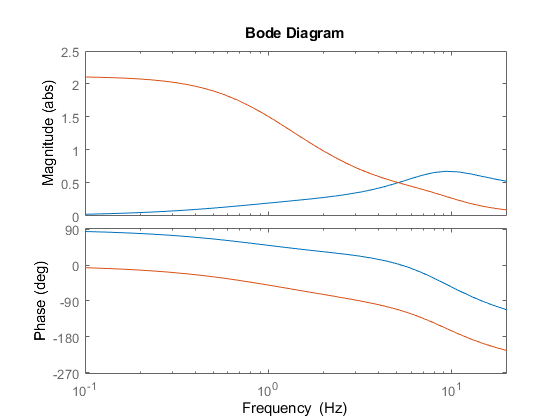


h = bodeplot(G_head, G_body);
setoptions(h,'FreqUnits','Hz', 'MagUnits', 'abs', ...
    'PhaseMatching', 'on', 'PhaseMatchingFreq', 1, 'PhaseMatchingValue', 0)
xlim([0.1 20])